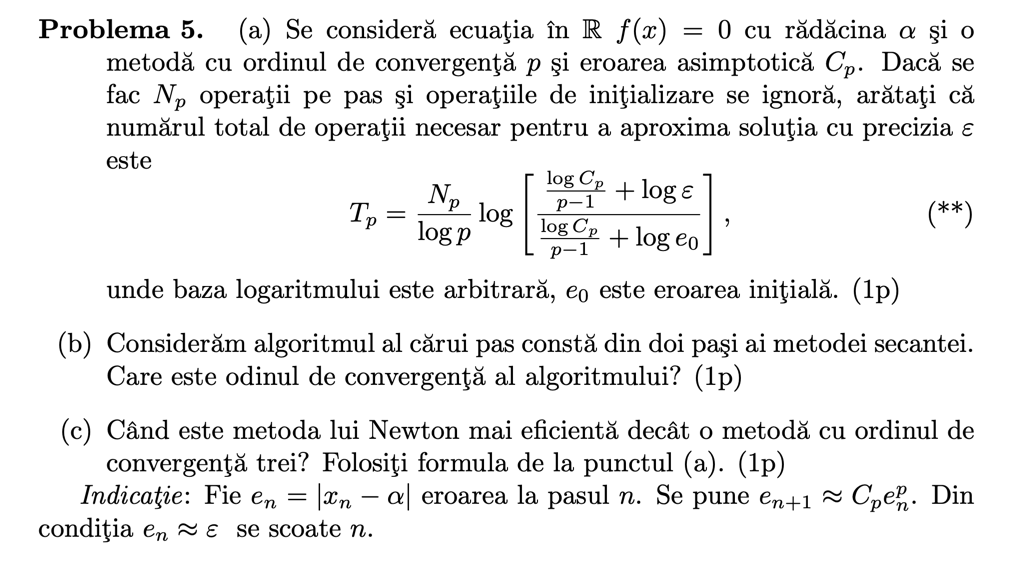

## Solutie

### Subpunctul (a)

Ordinul de convergenta: $p$

Eroarea asimptotica: $C_p =\frac{\phi^{\left(p\right)} \left(\alpha \right)}{p!}$

Daca $N_p \;\mathrm{ar}\;\mathrm{fi}\;1$, atunci eroarea s-ar dezvolta astfel per pas:

$e_{n+1} \sim C_p \cdot e_n^p$.

Fie $n$ numarul de pasi efectuati pentru a se ajunge la precizia dorita $\epsilon$. Atunci putem gasi formula reducerii erorii ca fiind:

$e_n \sim C_p^{1+p^2 +p^3 +\ldotsp^{n-1} } \cdot e_0^{p^n } =C_p^{\frac{p^n -1}{p-1}} \cdot e_0^{p^n }$.

Numarul de pasi $n$ este dat de relatia $e_n <\epsilon$. Deci obtinem relatia:


$$C_p^{\frac{p^n -1}{p-1}} \cdot e_0^{p^n } <\epsilon$$


Aplicam un logaritm (cu baza arbitrara) in ambele parti, vom obtine:


$$\begin{array}{l}
\log \left(C_p^{\frac{p^n -1}{p-1}} \cdot e_0^{p^n } \right)<\log \left(\epsilon \right)\Leftrightarrow \frac{p^n -1}{p-1}\log \left(C_p \right)+p^n \log \left(e_0 \right)<\log \left(\epsilon \right)\Leftrightarrow \\
\Leftrightarrow \;\frac{p^n }{p-1}\log \left(C_p \right)+p^n \log \left(e_0 \right)<\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)\Leftrightarrow p^n \left(\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)\right)<\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)\Leftrightarrow \\
\Leftrightarrow p^n <\frac{\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)}
\end{array}$$


Logaritmam din nou rezultatul obtinut anterior. Vom obtine:


$$n\;\log \left(p\right)<\log \left\lbrack \frac{\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)}\right\rbrack \;\Leftrightarrow n<\frac{1}{\log \left(p\right)}\log \left\lbrack \frac{\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)}\right\rbrack$$


Deoarece, pentru a aproxima cu precizia $\epsilon$ este necesara gasirea lui $n$ minim astfel incat inegalitatea trecuta sa fie transformata in egalitate, putem exprima pe $n$ necesar pentru a atinge precizia $\epsilon$ astfel:

$n\sim \frac{1}{\log \left(p\right)}\log \left\lbrack \frac{\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)}\right\rbrack$.

Daca vom face $N_p$ operatii per iteratie, atunci totalul numarului de operatii $T_p$ poate fi exprimat ca $T_n =n\cdot N_p$ (numarul de iteratii inmultit cu numarul de operatii facute per pas), deci, $n$ poate fi exprimat ca $\frac{T_n }{N_p }$.

Inlocuind in pasul anterior, numarul total de operatii necesare pentru a obtine precizia $\epsilon$ este:


$$T_p \sim \frac{N_p }{\log \left(p\right)}\log \left\lbrack \frac{\frac{\log \left(C_p \right)}{p-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_p \right)}{p-1}+\log \left(e_0 \right)}\right\rbrack$$


### Subpunctul (b)

Ordinul de convergenta al metodei secantei este dat de $p=\frac{1+\sqrt{5}}{2}\sim 1\ldotp 61803\ldotp \ldotp \ldotp$ (sursa: curs)

p=(1+sqrt(5))/2

p =           1.61803398874989


Daca aplicăm doi pasi ai metodei secantei in acelasi timp asta ar insemna ca vom face 2 pasi deodata:


$$e_{n+2} \sim C_p \cdot e_{n+1}^p ~C_p \;{\left(C_p \cdot e_n^p \right)}^p =C_p^2 \cdot e_n^{p^2 }$$


Deci un algoritm in care metoda secantei este aplicata de 2 ori la fiecare pas duce la cresterea patratica a eroarei asimptotice $\left(C_p \to C_p^2 \right)$, dar si la cresterea patratica a ordinului de convergenta $\left(p\to p^2 \right)$. Deci noul ordin de convergenta al algoritmului in care metoda secantei este aplicata de 2 ori per pas va fi:


$$p^{\prime } =p^2 ={\left(\frac{1+\sqrt{5}}{2}\right)}^2 =2\ldotp 61803\ldotp \ldotp \ldotp$$


pp=((1+sqrt(5))/2)^2

pp =           2.61803398874989


### Subpunctul (c)

Metoda lui Newton are ordinul de convergenta $p=2$ si eroarea asimptotica $C_2$. Fie un algoritm cu ordinul de convergenta $p=3$ si eroarea asimptotica $C_3$.

Numarul total de operatii facute de algoritmul lui Newton este:


$$T_2 =\frac{N_2 }{\log \left(2\right)}\log \left\lbrack \frac{\frac{\log \left(C_2 \right)}{2-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_2 \right)}{2-1}+\log \left(e_0 \right)}\right\rbrack =\frac{N_2 }{\mathrm{log2}}\log \left\lbrack \frac{\log \left(C_2 \right)+\log \left(\epsilon \right)}{\log \left(C_2 \right)+\log \left(e_0 \right)}\right\rbrack$$


Numarul total de operatii facute de algoritmul cu ordinul $p=3$ este:


$$T_3 =\frac{N_3 }{\log \left(3\right)}\log \left\lbrack \frac{\frac{\log \left(C_3 \right)}{3-1}+\log \left(\epsilon \right)}{\frac{\log \left(C_3 \right)}{3-1}+\log \left(e_0 \right)}\right\rbrack =\frac{N_3 }{\log \left(3\right)}\log \left\lbrack \frac{\log \left(C_3 \right)+2\cdot \log \left(\epsilon \right)}{\log \left(C_3 \right)+2\cdot \log \left(e_0 \right)}\right\rbrack$$


Pentru ca metoda lui Newton sa fie mai eficienta decat metoda a doua, este necesar ca:

$T_2 <T_3 \Leftrightarrow \frac{N_2 }{\mathrm{log2}}\log \left\lbrack \frac{\log \left(C_2 \right)+\log \left(\epsilon \right)}{\log \left(C_2 \right)+\log \left(e_0 \right)}\right\rbrack <\frac{N_3 }{\log \left(3\right)}\log \left\lbrack \frac{\log \left(C_3 \right)+2\cdot \log \left(\epsilon \right)}{\log \left(C_3 \right)+2\cdot \log \left(e_0 \right)}\right\rbrack$.

Deoarece $\epsilon$ si $e_0$ sunt constante, ele nu vor influenta inegalitatea. Este clar ca $\epsilon <\epsilon_0$.

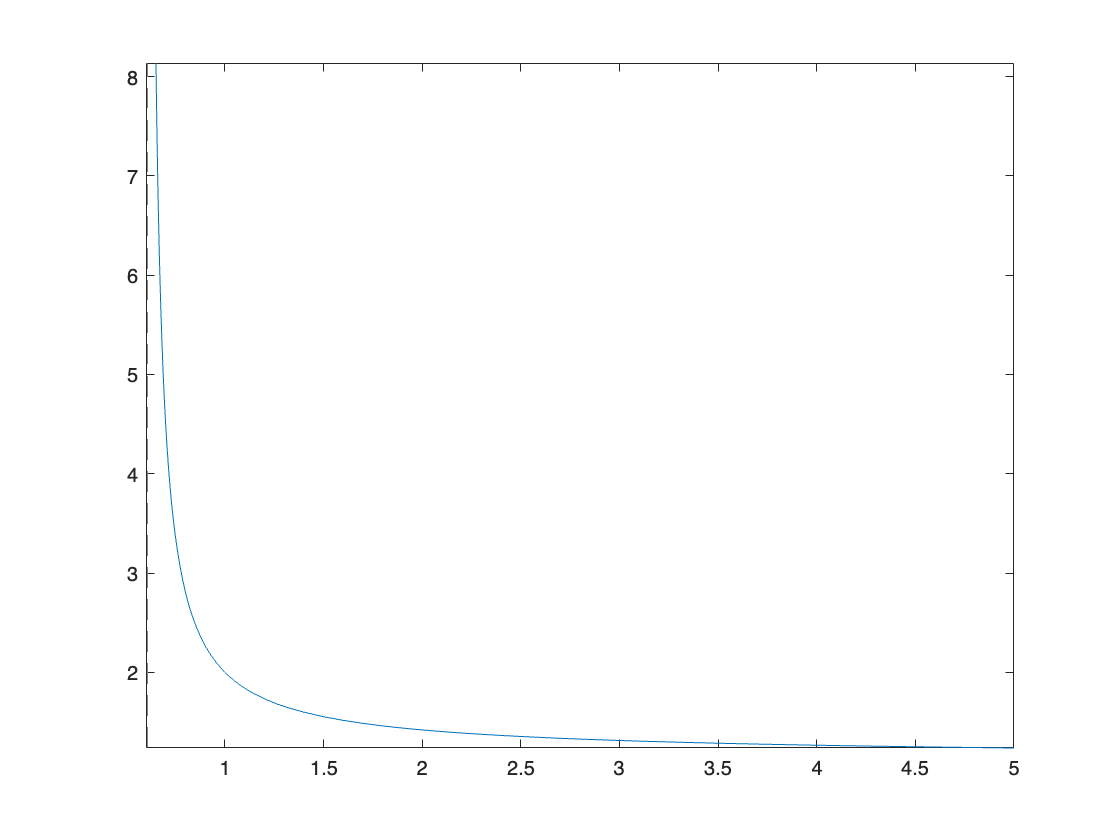

fplot(@(x) (log(x)+1)./(log(x)+0.5), [0.6 5])

Se observa ca o functie de tipul $\frac{\log \left(x\right)+a}{\log \left(x\right)+b},a>b$ este descrescatoare, deci un $C_2 >C_3$ este mai favorabil. De asemenea, $N_2 <N_3$ ar ajuta algoritmul lui Newton sa fie mai rapid decat cel cu ordinul de convergenta $p=3$.

Deci, metoda lui Newton va fi mai eficienta decat o metoda cu ordinul de convergenta de complexitate $p=3$ cand numarul de operatii per pas este mai mic $\left(N_2 \ll N_3 \right)$ si cand eroarea asimptotica devine mai mare $\left(C_2 \gg C_3 \right)$.